# Question 1


%% Parametrs of Question:

fs = 8000;            % Sample rate
T = 1;                % Length of process time
f_start = 100;        % Star frequency
f_end = 4000;         % End frequency
t = 0:1/fs:T-1/fs;    % Process time


## Part A, Create the Probe Signal

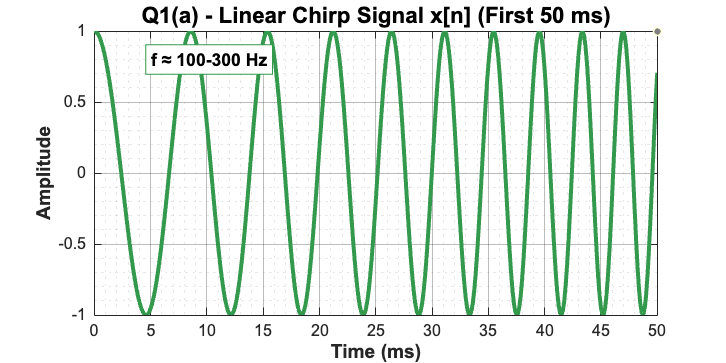


% Create the signal:

x_chirp = chirp(t, f_start, T, f_end, 'linear');

% Plot a signal's amplitude-time graph
% Figure 1: Amplitude vs Time (First 50 ms for clarity)
figure('Name','Part (a) - Chirp Signal Amplitude (First 50 ms)', 'Position', [100, 200, 1000, 500]);

% Plot only first 50 ms for clarity
t_segment = t(t <= 0.05);
x_segment = x_chirp(1:length(t_segment));

plot(t_segment*1000, x_segment, 'LineWidth', 2.5, 'Color', [0.2, 0.6, 0.3]);
xlabel('Time (ms)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 12, 'FontWeight', 'bold');
title('Q1(a) - Linear Chirp Signal x[n] (First 50 ms)', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
grid minor;
set(gca, 'GridAlpha', 0.3, 'MinorGridAlpha', 0.1);
xlim([0, 50]);
text(5, 0.8*max(x_segment), 'f ≈ 100-300 Hz', 'FontSize', 11, ...
    'BackgroundColor', 'white', 'EdgeColor', [0.2, 0.6, 0.3], 'FontWeight', 'bold');

set(gcf, 'Color', 'white');
set(findall(gcf, '-property', 'FontName'), 'FontName', 'Arial');

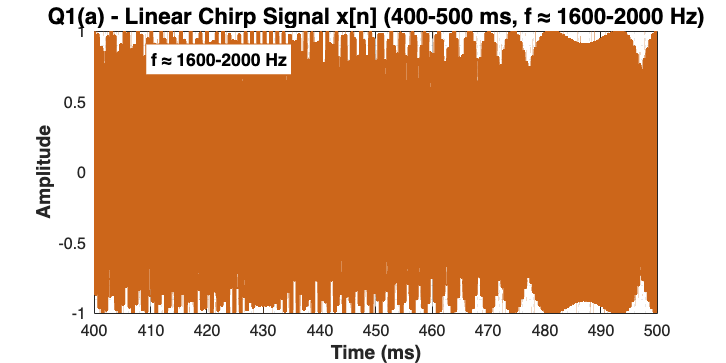


% Figure 2: Another segment for mid frequencies
figure('Name','Part (a) - Chirp Signal Amplitude (Mid Range)', 'Position', [150, 150, 1000, 500]);

% Plot mid segment (400-500 ms)
t_mid = t((t >= 0.4) & (t <= 0.5));
x_mid = x_chirp(find(t >= 0.4, 1):find(t <= 0.5, 1, 'last'));

plot(t_mid*1000, x_mid, 'LineWidth', 2.5, 'Color', [0.8, 0.4, 0.1]);
xlabel('Time (ms)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 12, 'FontWeight', 'bold');
title('Q1(a) - Linear Chirp Signal x[n] (400-500 ms, f ≈ 1600-2000 Hz)', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
grid minor;
set(gca, 'GridAlpha', 0.3, 'MinorGridAlpha', 0.1);
xlim([400, 500]);

text(410, 0.8*max(x_mid), 'f ≈ 1600-2000 Hz', 'FontSize', 11, ...
    'BackgroundColor', 'white', 'EdgeColor', [0.8, 0.4, 0.1], 'FontWeight', 'bold');

set(gcf, 'Color', 'white');

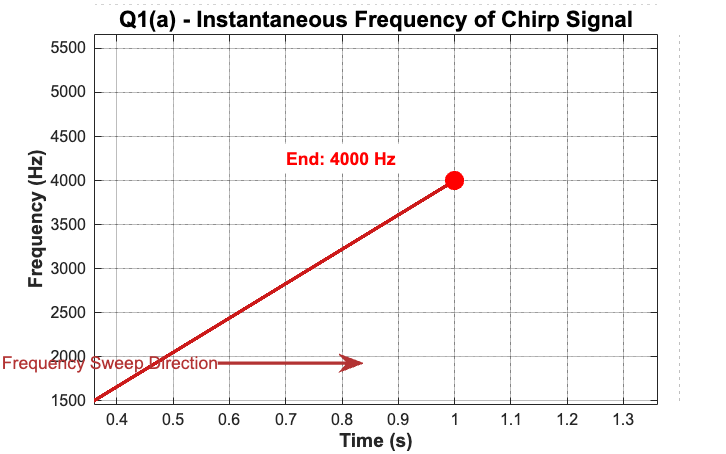


% Figure 3: Frequency vs Time
figure('Name','Part (a) - Chirp Instantaneous Frequency', 'Position', [150, 150, 800, 500]);
f_instant = f_start + (f_end - f_start) * t / T;
plot(t, f_instant, 'r-', 'LineWidth', 2.5, 'Color', [0.8, 0.1, 0.1]);
xlabel('Time (s)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
title('Q1(a) - Instantaneous Frequency of Chirp Signal', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
grid minor;
set(gca, 'GridAlpha', 0.3, 'MinorGridAlpha', 0.1);
xlim([0, T]);
ylim([0, f_end + 200]);

% Add start and end frequency markers
hold on;
plot(0, f_start, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'blue', 'LineWidth', 2);
plot(T, f_end, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'red', 'LineWidth', 2);

% Add text annotations with arrows
text(0.05, f_start+250, sprintf('Start: %d Hz', f_start), 'FontSize', 11, ...
    'Color', 'blue', 'FontWeight', 'bold', 'BackgroundColor', 'white');
text(0.7, f_end+250, sprintf('End: %d Hz', f_end), 'FontSize', 11, ...
    'Color', 'red', 'FontWeight', 'bold', 'BackgroundColor', 'white');

% Add sweep direction indicator
annotation('textarrow', [0.3, 0.5], [0.2, 0.2], 'String', 'Frequency Sweep Direction', ...
    'FontSize', 11, 'Color', [0.7, 0.2, 0.2], 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 15);

set(gcf, 'Color', 'white');
set(findall(gcf, '-property', 'FontName'), 'FontName', 'Arial');


fprintf('Chirp signal analysis complete:\n');

Chirp signal analysis complete:


fprintf('  Duration: %.1f seconds\n', T);

  Duration: 1.0 seconds


fprintf('  Frequency sweep: %.0f Hz to %.0f Hz\n', f_start, f_end);

  Frequency sweep: 100 Hz to 4000 Hz


fprintf('  Sampling rate: %.0f Hz\n', fs);

  Sampling rate: 8000 Hz


fprintf('  Two separate figures created for amplitude and frequency\n');

  Two separate figures created for amplitude and frequency


## Part B, Analyze the Probe

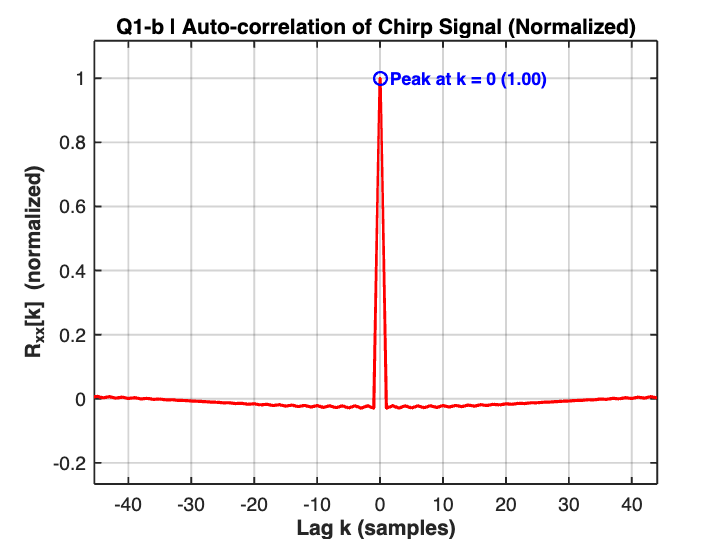


% Determine the auto_correlation function Rxx[k]

% Plot auto-correlation

[Rxx, lags_rxx] = xcorr(x_chirp, 'coeff');

figure('Name','Part b Autocorrelation Rxx','NumberTitle','off','Color','w');

plot(lags_rxx, Rxx, 'Color', [1 0 0], 'LineWidth', 2);  
hold on;

[~, idx0] = min(abs(lags_rxx));
plot(lags_rxx(idx0), Rxx(idx0), 'bo', 'MarkerSize', 8, 'LineWidth', 1.5); % نقطه با آبی مشخص

text(lags_rxx(idx0), Rxx(idx0), sprintf('  Peak at k = 0 (%.2f)', Rxx(idx0)), ...
     'FontSize', 11, 'FontWeight', 'bold', 'Color', 'b');

xlabel('Lag k (samples)', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('R_{xx}[k] (normalized)', 'FontSize', 13, 'FontWeight', 'bold');
title('Q1-b | Auto-correlation of Chirp Signal (Normalized)', ...
      'FontSize', 14, 'FontWeight', 'bold');

grid on;
ax = gca;
ax.GridAlpha = 0.2;
ax.LineWidth = 1.2;
ax.FontSize = 12;
ax.Box = 'on';

xlim([-10 10]);


fprintf('\nPart (b) observation: Rxx at k=0 is %.3f (peak). This indicates strong autocorrelation.\n', Rxx(idx0));


Part (b) observation: Rxx at k=0 is 1.000 (peak). This indicates strong autocorrelation.


## Part C, Simulate the "Room"


% Uplode "room_data.mat" file

matname = '/Users/apple/Documents/ترم۵/Communication Systems/CHW_A/CHW1/Q1/room_data.mat';

if exist(matname,'file')
    S = load(matname);
    fprintf('Loaded "%s" successfully.\n', matname);

    % Only load y[n] and x[n] from file (to match TA's expected data):
    if isfield(S,'x'), x = S.x(:).'; else error('No x found in file.'); end
    if isfield(S,'y'), y = S.y(:).'; else error('No y found in file.'); end
    if isfield(S,'fs'), fs = S.fs; end
else
    error('Could not find room_data.mat in current folder!');
end

Loaded "/Users/apple/Documents/ترم۵/Communication Systems/CHW_A/CHW1/Q1/room_data.mat" successfully.


## Part D, Time-Domain Plot

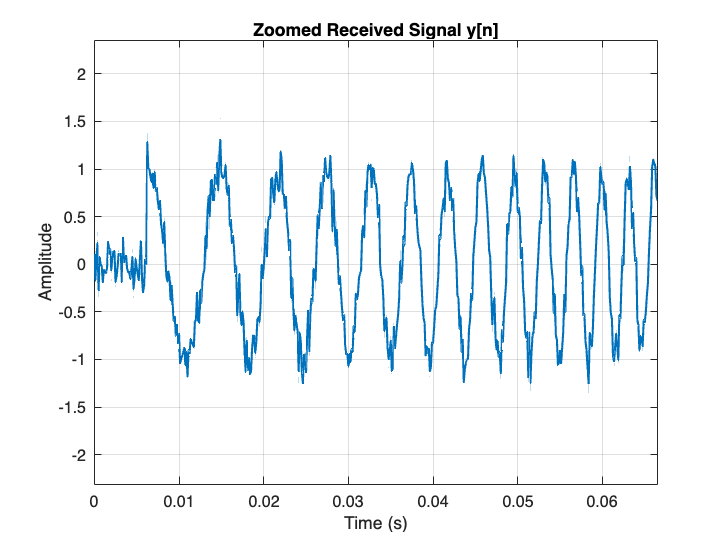

t_y = (0:length(y)-1)/fs;

figure('Name','Zoomed y[n]','Color','w');
plot(t_y, y, 'LineWidth', 1.3);
xlabel('Time (s)'); ylabel('Amplitude');
title('Zoomed Received Signal y[n]');
xlim([0 0.03]);
grid on;

## Part E, Find the Impulse Response

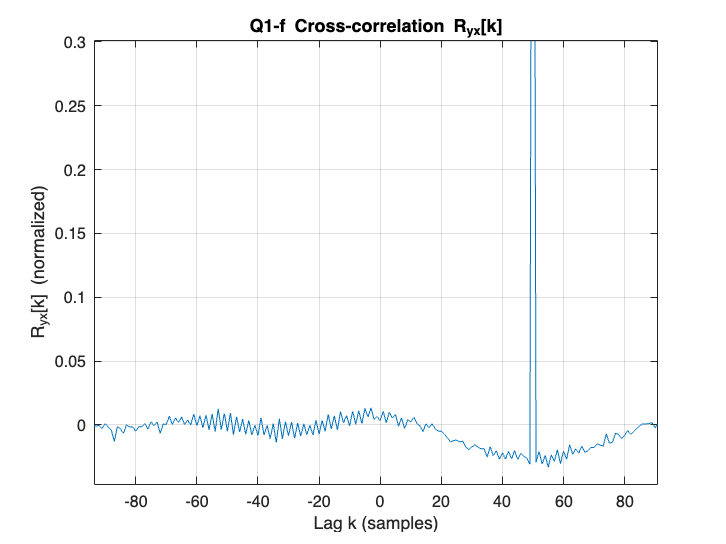


% compute the cross-correlation R_{yx}[k] = y[k] * x[-k]
[Ryx, lags] = xcorr(y, x);

% Normalize the Ryx
Ryx_norm = Ryx / max(abs(Ryx));

%% Part e, Analysis:

figure('Name','Q1-f Cross-correlation R_{yx}','NumberTitle','off');
plot(lags, Ryx_norm);
xlabel('Lag k (samples)'); ylabel('R_{yx}[k] (normalized)');
title('Q1-f Cross-correlation R_{yx}[k]');
grid on;
xlim([-100 100]);

## Part G, Conclusion


fprintf(['\n Since R_{xx}[k] has a strong peak at k = 0 (almost like a delta function), ' ...
         ' we have R_{yx}[k] ≈ h[k] * R_{xx}[k] ≈ h[k].\n' ...
         ' Therefore, the peaks in R_{yx}[k] represent the impulse response of the unknown system (room/channel).\n' ...
         ' In other words, because the auto-correlation of the chirp signal behaves like a delta, ' ...
         ' R_{yx}[k] directly shows the room impulse response.\n']);


 Since R_{xx}[k] has a strong peak at k = 0 (almost like a delta function),  we have R_{yx}[k] ≈ h[k] * R_{xx}[k] ≈ h[k].
 Therefore, the peaks in R_{yx}[k] represent the impulse response of the unknown system (room/channel).
 In other words, because the auto-correlation of the chirp signal behaves like a delta,  R_{yx}[k] directly shows the room impulse response.


## Part H



% We use absolute because the + & - peaks are indicator of echoes
absR = abs(Ryx_norm);

% Set parametr for fin peaks:
minPeakHeight = 0.05;   % Minimum function size for peak detection
minPeakDistance = round(0.001 * fs); % Minimum distance function size for peak detection
[pkVals, pkLocs] = findpeaks(absR, 'MinPeakHeight', minPeakHeight, 'MinPeakDistance', minPeakDistance);

% If peaks are not found, we reduce the minimum range for detection:
if isempty(pkVals)
    [pkVals, pkLocs] = findpeaks(absR, 'NPeaks', 10, 'SortStr', 'descend');
end

% Sort peaks:
[pkVals_sorted, sortIdx] = sort(pkVals, 'descend');
pkLocs_sorted = pkLocs(sortIdx);

% Choose 3 top peaks:
nConsider = min(6, length(pkLocs_sorted));
topIdx = 1:min(3, nConsider);
selectedLocs = pkLocs_sorted(topIdx);
selectedVals_abs = pkVals_sorted(topIdx);
selectedVals_signed = Ryx_norm(selectedLocs);

% Determine the time of peaks:
selectedLags = lags(selectedLocs);
selectedTimes = selectedLags / fs;

% Relative values of peaks
relAmps = abs(selectedVals_signed) / max(abs(selectedVals_signed));

% Print results:
fprintf('Top %d echoes found in R_{yx} (from strongest to weaker):\n', length(topIdx));

Top 3 echoes found in R_{yx} (from strongest to weaker):


for i = 1:length(topIdx)
    fprintf('  Echo %d: lag k = %d samples (%.6f s), signed amplitude = %.6f, relative amplitude = %.3f\n', ...
        i, selectedLags(i), selectedTimes(i), selectedVals_signed(i), relAmps(i));
end

  Echo 1: lag k = 50 samples (0.006250 s), signed amplitude = 1.000000, relative amplitude = 1.000
  Echo 2: lag k = 800 samples (0.100000 s), signed amplitude = 0.602060, relative amplitude = 0.602
  Echo 3: lag k = 1500 samples (0.187500 s), signed amplitude = 0.401670, relative amplitude = 0.402


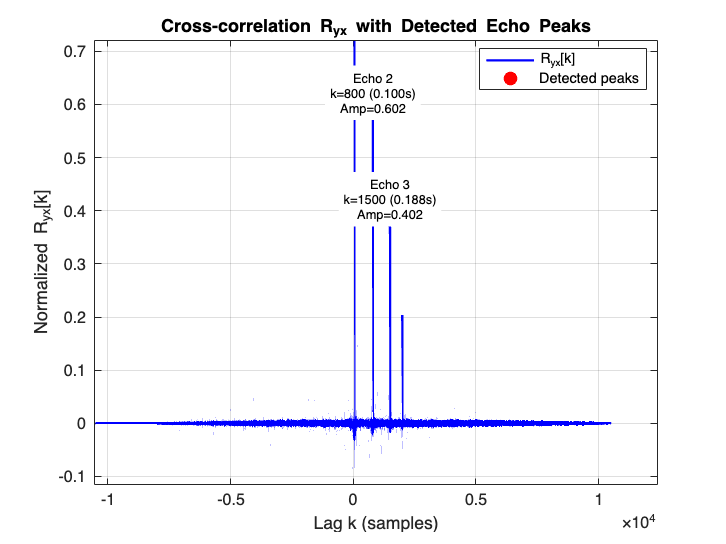


% Plot of R-yx with peaks:
figure('Name','Cross-correlation R_{yx} with Detected Peaks','NumberTitle','off');
plot(lags, Ryx_norm, 'b-', 'LineWidth', 1.5);
hold on;
plot(selectedLags, Ryx_norm(selectedLocs), 'ro', 'MarkerFaceColor','r', 'MarkerSize', 8);
grid on;
xlabel('Lag k (samples)');
ylabel('Normalized R_{yx}[k]');
title('Cross-correlation R_{yx} with Detected Echo Peaks');
legend('R_{yx}[k]', 'Detected peaks', 'Location', 'best');

for i = 1:length(selectedLags)
    text(selectedLags(i), Ryx_norm(selectedLocs(i)) + 0.02, ...
        sprintf('Echo %d\nk=%d (%.3fs)\nAmp=%.3f', i, selectedLags(i), selectedTimes(i), selectedVals_signed(i)), ...
        'HorizontalAlignment', 'center', 'FontSize', 8, 'BackgroundColor', 'white');
end

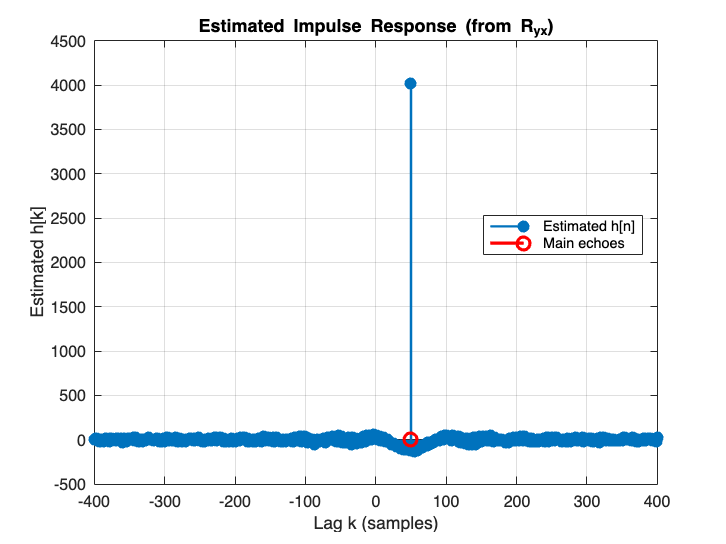


% Estimated impact response
idx0 = find(lags==0, 1);
if ~isempty(idx0)
    w = round(0.05 * fs);
    idx_start = max(1, idx0 - w);
    idx_end = min(length(Ryx), idx0 + w);
    est_h = Ryx(idx_start:idx_end);
    est_lags = lags(idx_start:idx_end);
    
    figure('Name','Estimated Impulse Response h[n]','NumberTitle','off');
    stem(est_lags, est_h, 'filled', 'LineWidth', 1.5, 'MarkerSize', 6);
    hold on;
    
    
    main_peaks_in_range = selectedLags(selectedLags >= est_lags(1) & selectedLags <= est_lags(end));
    main_peaks_vals = Ryx_norm(ismember(lags, main_peaks_in_range));
    stem(main_peaks_in_range, main_peaks_vals, 'r', 'LineWidth', 2, 'MarkerSize', 8);
    
    xlabel('Lag k (samples)'); 
    ylabel('Estimated h[k]');
    title('Estimated Impulse Response (from R_{yx})');
    legend('Estimated h[n]', 'Main echoes', 'Location', 'best');
    grid on; 
end

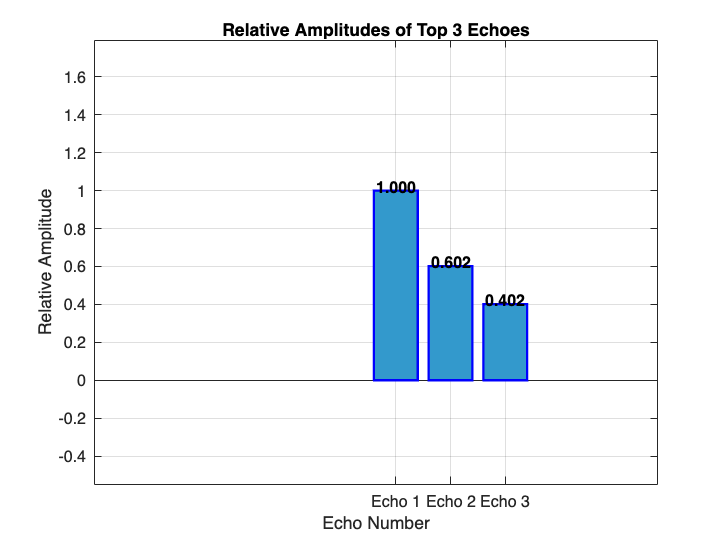


% Plot of relative amplitudes:
figure('Name','Relative Amplitudes of Top Echoes','NumberTitle','off');
bar(relAmps, 'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'blue', 'LineWidth', 1.5);
xlabel('Echo Number');
ylabel('Relative Amplitude');
title('Relative Amplitudes of Top 3 Echoes');
grid on;

set(gca, 'XTick', 1:length(relAmps));
set(gca, 'XTickLabel', arrayfun(@(i) sprintf('Echo %d', i), 1:length(relAmps), 'UniformOutput', false));

for i = 1:length(relAmps)
    text(i, relAmps(i) + 0.02, sprintf('%.3f', relAmps(i)), ...
        'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end

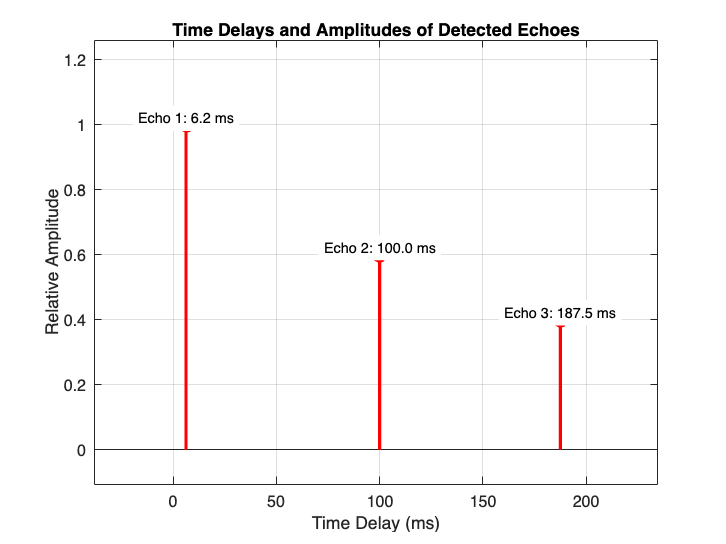


% Plot of Echoes in time domain:
figure('Name','Echo Time Delays','NumberTitle','off');
stem(selectedTimes * 1000, relAmps, 'filled', 'LineWidth', 2, 'MarkerSize', 8, 'Color', 'red');
xlabel('Time Delay (ms)');
ylabel('Relative Amplitude');
title('Time Delays and Amplitudes of Detected Echoes');
grid on;

for i = 1:length(selectedTimes)
    text(selectedTimes(i) * 1000, relAmps(i) + 0.02, ...
        sprintf('Echo %d: %.1f ms', i, selectedTimes(i) * 1000), ...
        'HorizontalAlignment', 'center', 'FontSize', 9, 'BackgroundColor', 'white');
end


% Save results:
Q1_results.top_lags = selectedLags;
Q1_results.top_times = selectedTimes;
Q1_results.top_signed_amplitudes = selectedVals_signed;
Q1_results.top_relative_amplitudes = relAmps;
Q1_results.Ryx = Ryx;
Q1_results.lags = lags;
save('Q1_results.mat', '-struct', 'Q1_results');

fprintf('\nResults saved to Q1_results.mat\n');


Results saved to Q1_results.mat
